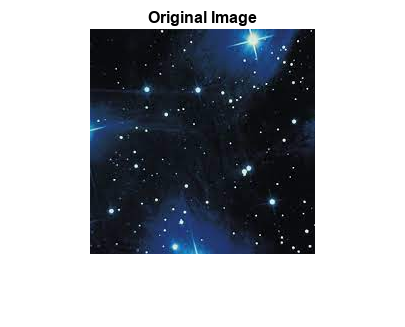

clear;   clc;   clf; 
I = imread("demo4.jpeg");
imshow(I)
title("Original Image");

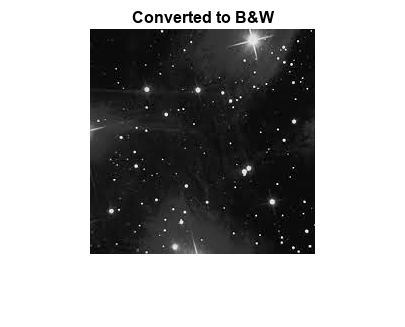

I1 = rgb2gray(I);
imshow(I1)
title("Converted to B&W")

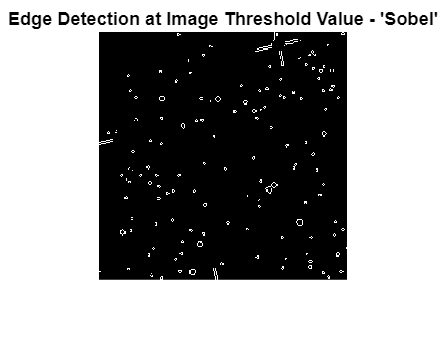

E1 = edge(I1,'sobel');
imshow(E1)
title("Edge Detection at Image Threshold Value - 'Sobel'")

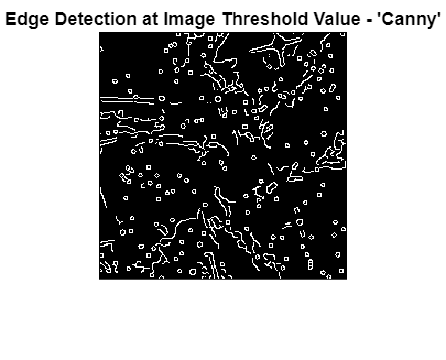

E2 = edge(I1,'canny');
imshow(E2)
title("Edge Detection at Image Threshold Value - 'Canny'")

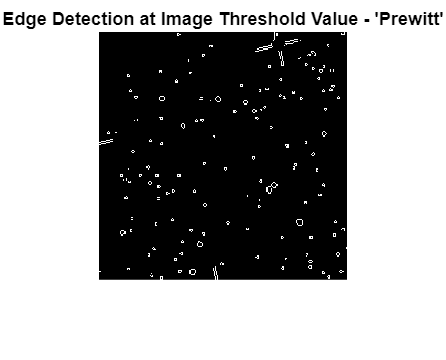

E3 = edge(I1,'prewitt');
imshow(E3)
title("Edge Detection at Image Threshold Value - 'Prewitt'")

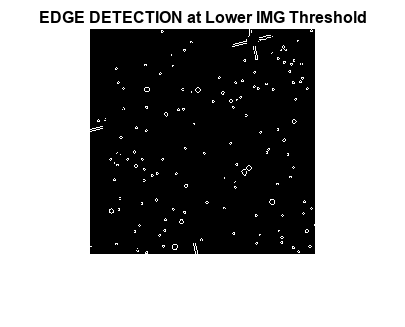

[~, threshold] = edge(I1, 'sobel');
Factor = 0.125;
E = edge(I1, 'sobel', threshold *1);
imshow(E)
title("EDGE DETECTION at Lower IMG Threshold")

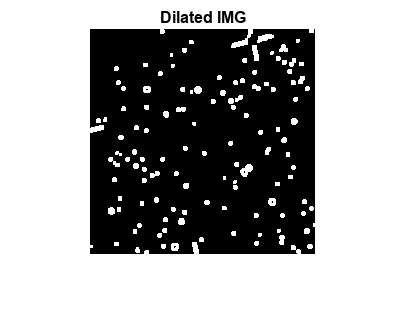

se0 = strel('line', 2, 0);
se45 = strel('line', 2, 45);
se90 = strel('line', 2, 90);
dil = imdilate(E, [se0, se90]);
imshow(dil)
title('Dilated IMG')

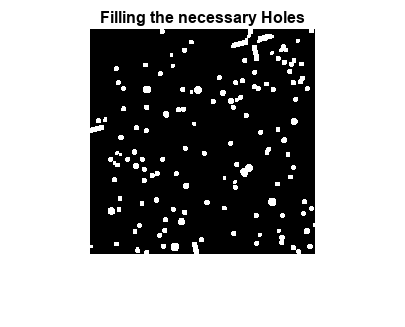

E_fill = imfill(dil, 'holes');
imshow(E_fill)
title("Filling the necessary Holes")

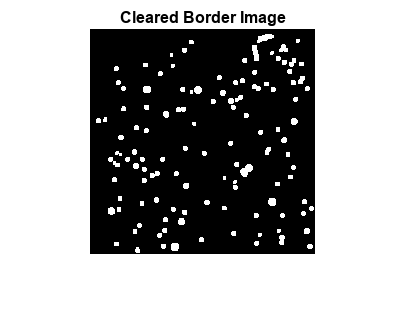

E_border = imclearborder(E_fill, 8);
imshow(E_border)
title('Cleared Border Image')

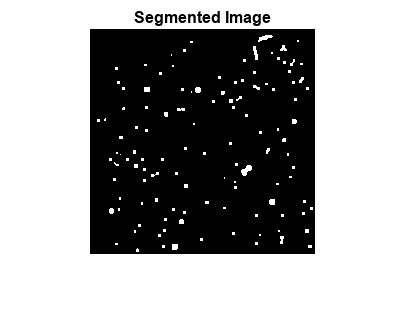

seD = strel("diamond", 1);
E_final = imerode(E_border, seD);
imshow(E_final)
title("Segmented Image");

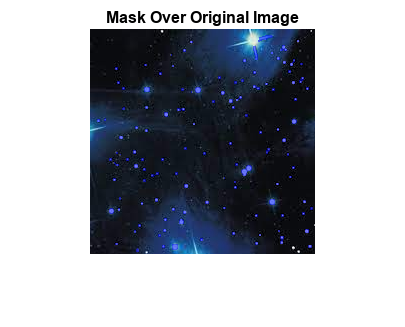

imshow(labeloverlay(I, E_final))
title('Mask Over Original Image')

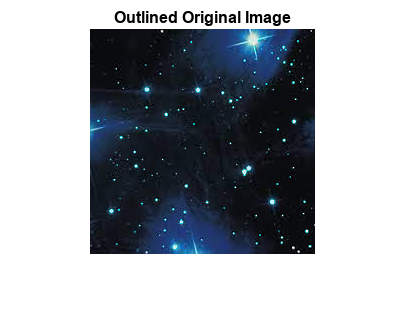

E_outline = bwperim(E_final, 8);
Segout = I; 
Segout(E_outline) = 24; 
imshow(Segout)
title("Outlined Original Image")

#### `Feature Extraction`

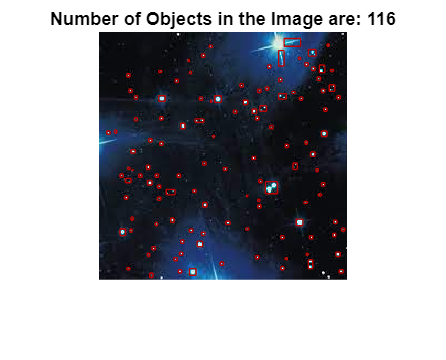

[labeled, numPersons] = bwlabel(E_final);
stats = regionprops(labeled, "Area", "BoundingBox", "Centroid");
boundingbox = [stats.BoundingBox];

hold on 
for i = 1 : length(stats)
    BB = stats(i).BoundingBox;
    rectangle('Position', [BB(1), BB(2), BB(3), BB(4)], 'EdgeColor', [0.75 0 0])
end
title(['Number of Objects in the Image are: ', num2str(numPersons)])
hold off